# Plotting the number of contributions in the topic of  NNs per layer per year

% Specify the Excel file name (replace with your file name)
filename = '2_count_per_layer_and_year.xlsx';

% Read the Excel file into a table
dataTable = readtable(filename);

% Display the imported data
disp('Imported Table:');

Imported Table:


disp(dataTable);

           Section            PublicationYear    Count
    ______________________    _______________    _____

    {'Bio-implementation'}         2004            1  
    {'Bio-implementation'}         2011            1  
    {'Bio-implementation'}         2014            1  
    {'Bio-implementation'}         2018            1  
    {'Bio-implementation'}         2019            1  
    {'Bio-implementation'}         2021            4  
    {'Bio-implementation'}         2022            3  
    {'Bio-implementation'}         2023            5  
    {'Bio-implementation'}         2024            4  
    {'Bio-implementation'}         2025            4  
    {'Dataset generation'}         2010            1  
    {'Dataset generation'}         2012            1  
    {'Dataset generation'}         2013            2  
    {'Dataset generation'}         2014            1  
    {'Dataset gen


% Find unique application entries
apps = unique(dataTable{:,1});
disp('Application entries:');

Application entries:


%switching entries
temp=apps{5};
apps{5}=apps{4};
apps{4}=temp;
disp(apps);

    {'Bio-implementation'}
    {'Dataset generation'}
    {'Explainability'    }
    {'PHY layer'         }
    {'MAC layer'         }
    {'Upper layers'      }



% Find unique years
years = unique(dataTable{:,2});
disp('Years:');

Years:


disp(years);

        2004
        2010
        2011
        2012
        2013
        2014
        2017
        2018
        2019
        2020
        2021
        2022
        2023
        2024
        2025




% Conforming a matrix where the rows refers to the applications and the
% columns refer to the year
app_per_year=zeros(numel(apps),numel(years));
% filling in the table
for i=1:numel(apps)%loop per application
    for j=1:numel(years)%loop per year
        %looking for the corresponding entry in the table
        idx=ismember(dataTable{:,1},apps{i}) & ismember(dataTable{:,2},years(j));
        idx_app_per_year=find(idx==1);
        %filling the data out
        if(~isempty(idx_app_per_year))
            app_per_year(i,j)=dataTable{idx_app_per_year,3};
        end
    end
end

% implementing the cumulative vie
app_per_year_cum=cumsum(app_per_year,2);

### Bar plot

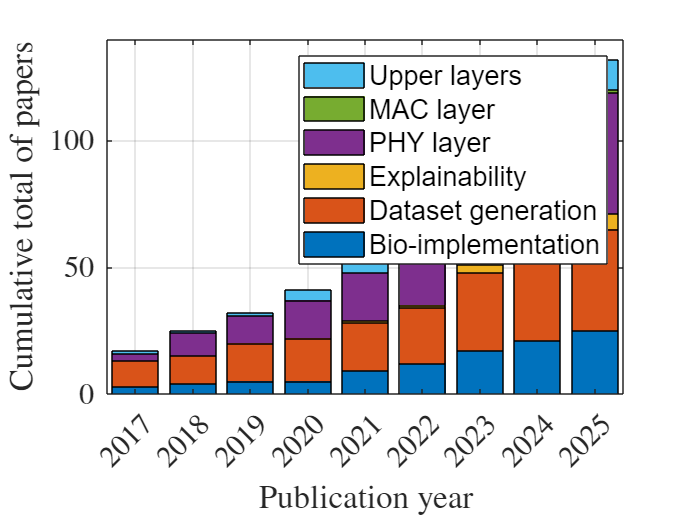

fontsize=15; %for plotting
figure;
bar(years,app_per_year_cum','stacked'); grid on;
xlabel('Publication year','Interpreter','latex');
ylabel('Cumulative total of papers','Interpreter','latex');
set(gca,'FontSize',fontsize);

year_vector=2017:2025;
set(gca, 'XTick', year_vector);
x_ticks=cell(1,length(year_vector));
for m=1:length(year_vector)
  x_ticks{m}=strcat("$",num2str(year_vector(m)),"$");
end
 
set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');
axis([2016.5 2025.5 0 140])
legend(apps);